addpath('./functions');
addpath('./data');

dataset = [];
classes = [];
for i=1:1
    str = ['data\cifar-10-batches-mat\data_batch_', num2str(i),'.mat'];
    load(str)
    dataset = [dataset; data];
    classes = [classes; labels];

end

load('data\cifar-10-batches-mat\test_batch.mat');

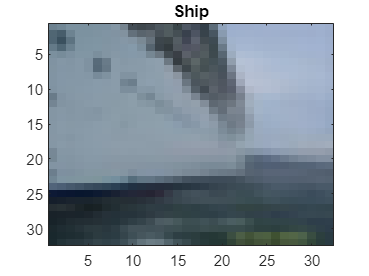

[permutedImageData, categoricalLabels] = permute_dataset(dataset, classes);
labels_names = ["Airplane", ...
                "Automobile", ...
                "Bird", ...
                "Cat", ...
                "Deer", ...
                "Dog", ...
                "Frog", ...
                "Horse", ...
                "Ship", ...
                "Truck", ...
                ];

labels_numbers = ["0", ...
                  "1", ...
                  "2", ...
                  "3", ...
                  "4", ...
                  "5", ...
                  "6", ...
                  "7", ...
                  "8", ...
                  "9", ...
                  ];

label2name = dictionary(labels_numbers, labels_names);
idx = randi(size(permutedImageData,4));

imagesc(permutedImageData(:,:,:,idx))
title(label2name(categoricalLabels(idx)))

% N = size(permutedImageData,4);
% k = round(0.2*N);
% indeces = randperm(N,k);
% permutedImageData = permutedImageData(:,:,:,indeces);
% categoricalLabels = categoricalLabels(indeces);

size(permutedImageData)

ans =           32          32           3       10000


test_size = 0.2

test_size = 0.2000

% normalizedData = normalize(permutedImageData);
[X_train, X_val, Y_train, Y_val] = train_test_split(permutedImageData, categoricalLabels, test_size);

layers = basic_cnn_classifier()

layers =   11×1 Layer array with layers:

     1   ''   Image Input             32×32×3 images with 'zerocenter' normalization
     2   ''   2-D Convolution         32 3×3 convolutions with stride [1  1] and padding 'same'
     3   ''   ReLU                    ReLU
     4   ''   2-D Convolution         32 3×3 convolutions with stride [1  1] and padding 'same'
     5   ''   ReLU                    ReLU
     6   ''   2-D Max Pooling         2×2 max pooling with stride [1  1] and padding [0  0  0  0]
     7   ''   Fully Connected         128 fully connected layer
     8   ''   ReLU                    ReLU
     9   ''   Fully Connected         10 fully connected layer
    10   ''   Softmax                 softmax
    11   ''   Classification Output   crossentropyex

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |        6.25% |       10.70% |       2.3091 |       2.3440 |          0.0010 |
|       1 |          50 |       00:00:04 |       25.00% |              |       2.1210 |              |          0.0010 |
|       1 |         100 |       00:00:07 |       26.56% |              |       1.9166 |              |          0.0010 |
|       2 |         150 |       00:00:15 |       31.25% |              |       1.9801 |              |          0.

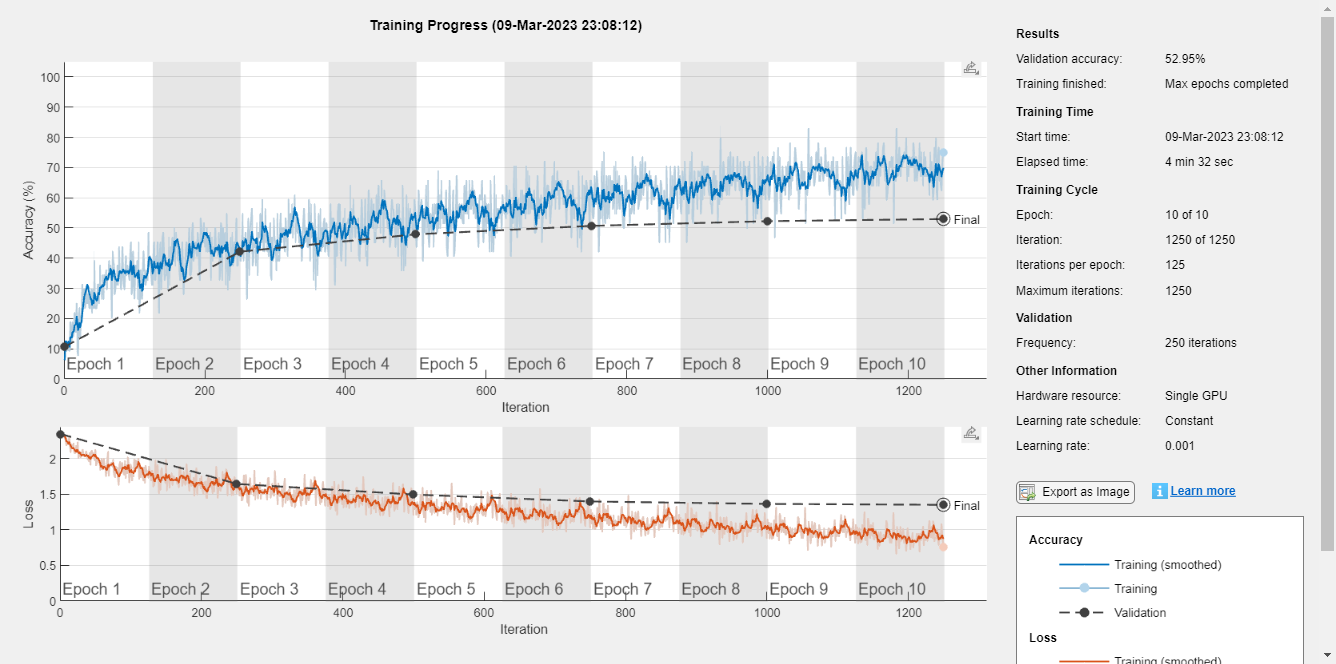

options = trainingOptions('sgdm', "ExecutionEnvironment","gpu",OutputNetwork="best-validation-loss",Plots="training-progress", MiniBatchSize=64, InitialLearnRate=0.001, MaxEpochs=10, ValidationData={X_val,Y_val}, ValidationFrequency=250);
net = trainNetwork(X_train,Y_train, layers, options);

[testData, testLabels] = permute_dataset(data,labels);

preds = net.classify(testData);
tp = nnz(preds == testLabels);
accuracy = tp / length(testLabels);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 52.83%


layers = improved_cnn_classifier();
options = trainingOptions('sgdm', "ExecutionEnvironment","gpu",OutputNetwork="best-validation-loss",Plots="training-progress", MiniBatchSize=64, InitialLearnRate=0.001, MaxEpochs=10, ValidationData={X_val,Y_val}, ValidationFrequency=250);
net = trainNetwork(X_train,Y_train, layers, options);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       10.94% |       13.50% |       2.5653 |       2.4281 |          0.0010 |
|       1 |          50 |       00:00:16 |       28.12% |              |       1.9032 |              |          0.0010 |
|       1 |         100 |       00:00:27 |       26.56% |              |       2.0132 |              |          0.0010 |
|       2 |         150 |       00:00:39 |       28.12% |              |       1.8748 |              |          0.

preds = net.classify(testData);
tp = nnz(preds == testLabels);
accuracy = tp / length(testLabels);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 52.55%
